# Reinforcement learning for financial trading Demo

## Building constant variables

Test and train data building

% Data Set - Simulating 3 stocks, $20,000, 15 years of Closing Prices
% Training Data ~ 12 years
% Test Data ~ 3 years

% Choose to simulate data or fetch real financial data
[trainData,testData] = simulateStockData;
% [trainData,testData] = fetchStockData;

## Action vectors creation

% Action Combinations for Stock
% 0 - sell, 1 - hold, 2 - buy
% This results in 27 Action combinations. E.g.:
% Action_Vectors = [0 0 0;0 0 1;...;1 1 0;1 1 1 ];
x = 0:1:2;
y = 0:1:2;
z = 0:1:2;
[X,Y,Z] = meshgrid(x,y,z);
for i = 1:numel(X)
    Action_Vectors(i,:) = [Z(i),X(i),Y(i)];
end

## Reset and step function creation

ResetHandle = @() myResetFunction(trainData);
StepHandle = @(Action,StockSaved) myStepFunction(Action,StockSaved,trainData,Action_Vectors,true);
ResetHandleT = @() myResetFunction(testData);
StepHandleT = @(Action,StockSaved) myStepFunction(Action,StockSaved,testData,Action_Vectors,false);

## Observation definition

% Input size of Actor / Critic is 19, which maps to the state vector. 
% For 3 stocks this state vector equals-
% 3 x Stocks Owned
% 3 x Price Different when Bought
% 1 x Cash In Hand
% 3 x Price change from yesterday
% 3 x Price change from 2 days ago
% 3 x Price change from 7 days ago
% 3 x Price change from average price of 7 days ago

ObservationInfo = rlNumericSpec([1 19]);
ObservationInfo.Name = 'StockTrading States';
%the description is a single string to describe the states
ObservationInfo.Description = ['stockholdings, ', ...
    'stock buy price difference, ', ' cash, ', 'StockInd1, ' , 'StockInd2, ', 'StockInd3 '];

## Action definition

ActionInfo = rlFiniteSetSpec(1:27);
ActionInfo.Name = 'Stock Actions';

## Environment creation

env = rlFunctionEnv(ObservationInfo,ActionInfo,StepHandle,ResetHandle);

Step: 2/2598 Action: 9 Profit: 26.667 Reward: -1 Reward action: 0


envT = rlFunctionEnv(ObservationInfo,ActionInfo,StepHandleT,ResetHandleT);

Step: 2/1114 Action: 19 Profit: -3488.4859 Reward: 1 Reward action: 0


## Creation of the AC Agent

Neural networks

criticNet = [
    imageInputLayer([1 19 1],"Name","state","Normalization","none")
    fullyConnectedLayer(128,"Name","Fully_128_1")
    tanhLayer("Name","tanh_activation1")
    fullyConnectedLayer(128,"Name","Fully_128_2")
    tanhLayer("Name","tanh_activation2")
    fullyConnectedLayer(64,"Name","Fully_64")
    reluLayer("Name","relu_activation1")
    fullyConnectedLayer(1,"Name","output")];

actorNet = [
    imageInputLayer([1 19 1],"Name","state","Normalization","none")
    fullyConnectedLayer(128,"Name","Fully_128_1")
    tanhLayer("Name","tanh_activation1")
    fullyConnectedLayer(128,"Name","Fully_128_2")
    tanhLayer("Name","tanh_activation2")
    fullyConnectedLayer(64,"Name","Fully_64")
    reluLayer("Name","relu_activation1")
    fullyConnectedLayer(27,"Name","action")];

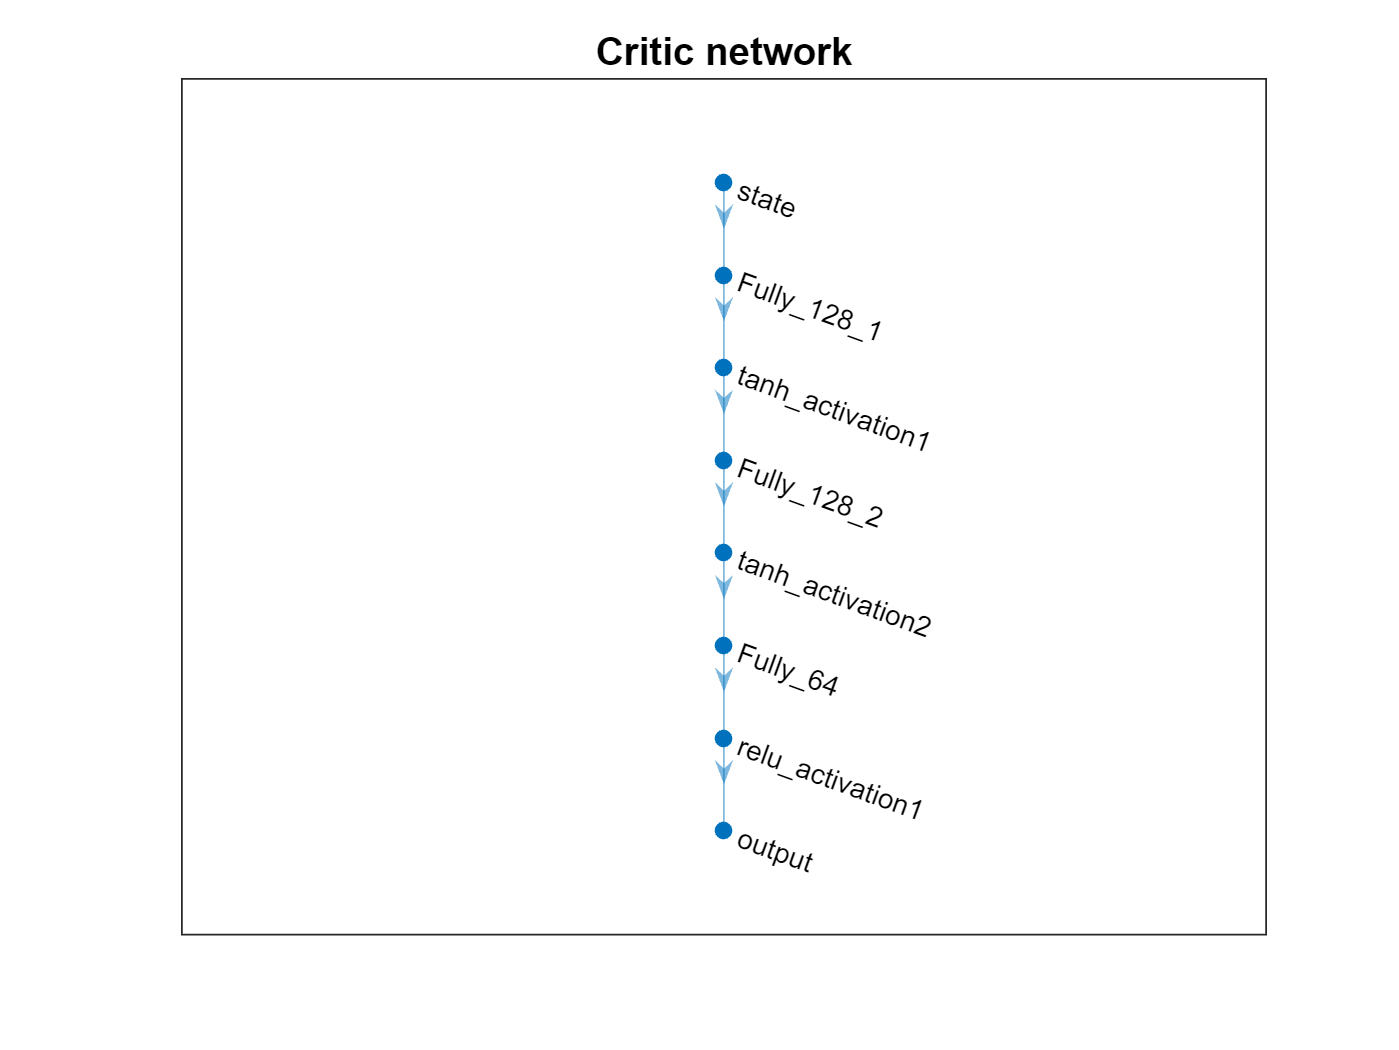

lgraph1 = layerGraph(criticNet);
lgraph2 = layerGraph(actorNet);

figure;
plot(lgraph1);
title('Critic network')

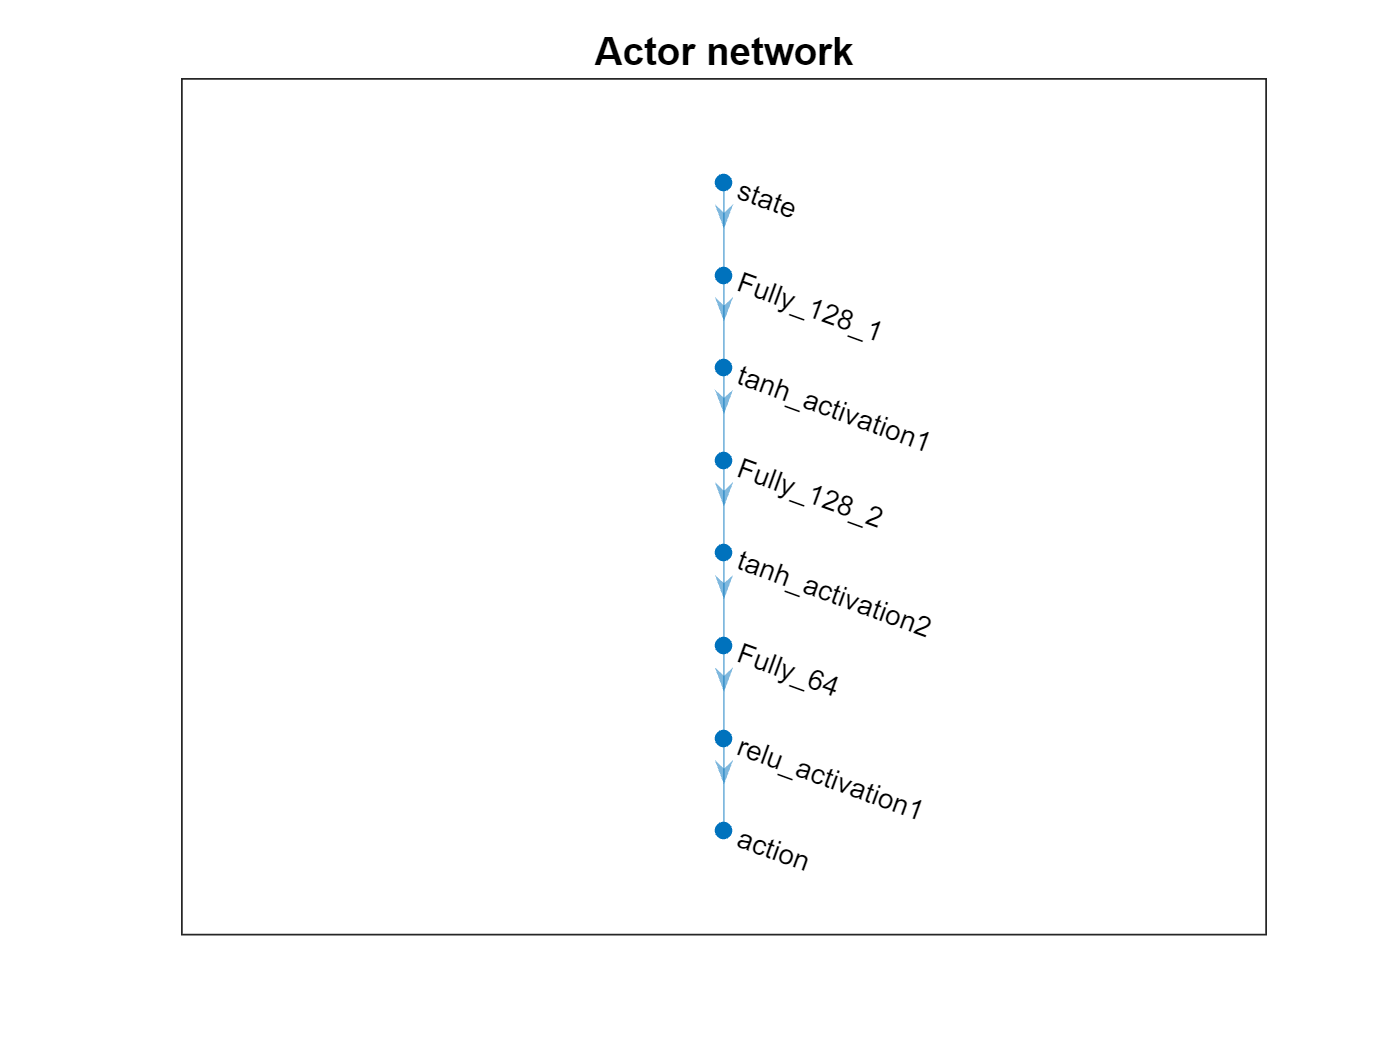

figure;
plot(lgraph2);
title('Actor network')

% Agent creation

obsInfo = getObservationInfo(env);
actInfo = getActionInfo(env);

criticOpts = rlRepresentationOptions('LearnRate',1e-3,'GradientThreshold',1,'UseDevice','cpu');
% 19b code 
% critic = rlRepresentation(criticNet,criticOpts,'Observation',{'state'},obsInfo);
% 20a code
critic = rlValueRepresentation(criticNet,obsInfo,'Observation',{'state'},criticOpts);

actorOpts = rlRepresentationOptions('LearnRate',1e-3,'GradientThreshold',1,'UseDevice','cpu');
% 19b code
% actor = rlRepresentation(actorNet,actorOpts,'Observation',{'state'},obsInfo,'Action',{'action'},actInfo);
% 20a code
actor = rlStochasticActorRepresentation(actorNet,obsInfo,actInfo,'Observation',{'state'},actorOpts);

agentOpts = rlACAgentOptions(...
    'NumStepsToLookAhead',64, ...
    'EntropyLossWeight', 0.3, ...
    'DiscountFactor',0.9);
agent = rlACAgent(actor,critic,agentOpts);

## Agent Training

Training options

trainOpts = rlTrainingOptions(...
    'MaxEpisodes', 5000, ...
    'MaxStepsPerEpisode', 4000, ...
    'Verbose', true, ...
    'Plots','training-progress',...
    'ScoreAveragingWindowLength',10,...
    'StopTrainingCriteria','AverageReward',...
    'StopTrainingValue',100000000,...
    'SaveAgentCriteria',"EpisodeReward" ,...
    'SaveAgentValue', 30000,...
    'SaveAgentDirectory', pwd + "\agents\");
% Agent training

doTraining = false;
if doTraining    
    % Train the agent.
    trainingStats = train(agent,env,trainOpts);
else
    % Load pretrained agent for the example.
    load('agent_3Stock_Jun03.mat','agent')       
end

## Simulation on Test data

Step: 2/1114 Action: 14 Profit: 4189.4095 Reward: 1 Reward action: 0
Step: 3/1114 Action: 14 Profit: 4185.319 Reward: -1 Reward action: 0
Step: 4/1114 Action: 25 Profit: 3826.7634 Reward: -1 Reward action: 0
Step: 5/1114 Action: 13 Profit: 3961.3081 Reward: 1 Reward action: 0
Step: 6/1114 Action: 11 Profit: 3472.6197 Reward: -1 Reward action: 0
Step: 7/1114 Action: 17 Profit: 4004.1654 Reward: 1 Reward action: 0
Step: 8/1114 Action: 14 Profit: 3938.6088 Reward: -1 Reward action: 0
Step: 9/1114 Action: 11 Profit: 4057.5143 Reward: 1 Reward action: 60.6531
Step: 10/1114 Action: 24 Profit: 5088.5879 Reward: -1 Reward action: 0
Step: 11/1114 Action: 13 Profit: 5403.7306 Reward: 1 Reward action: 66.602
Step: 12/1114 Action: 23 Profit: 5323.3624 Reward: -1 Reward action: 0
Step: 13/1114 Action: 14 Profit: 5497.1222 Reward: 1 Reward action: 0
Step: 14/1114 Action: 15 Profit: 6415.5573 Reward: 1 Reward action: 0
Step: 15/1114 Action: 20 Profit: 6275.4966 Reward: -2 Reward action: 40.3649
Step:

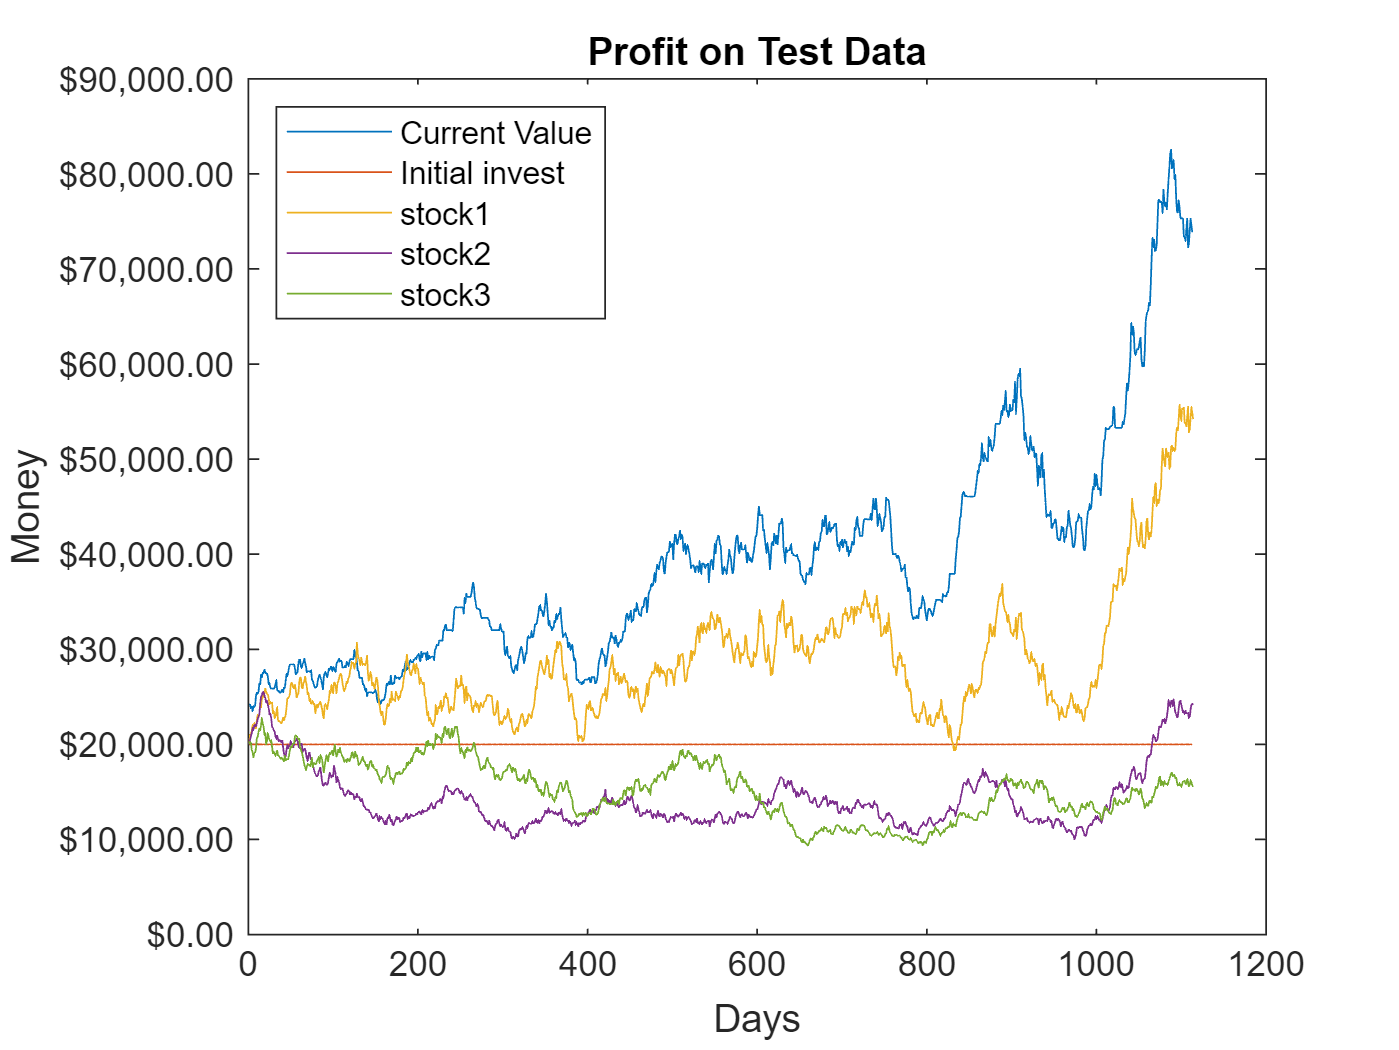

Step: 1114/1114 Action: 15 Profit: 53850.7382 Reward: -1 Reward action: 0


simOpts = rlSimulationOptions('MaxSteps',4000);
experience = sim(envT,agent,simOpts);

*Copyright 2020 The MathWorks, Inc.*